Load Data

format shortG
tregcon = readmatrix("normalized undiluted con 500000.xlsx");
day = tregcon(:,1);
t054 = tregcon(:,2);
t046 = tregcon(:,3);
t051 = tregcon(:,4);
t062 = tregcon(:,5);
t031 = tregcon(:,6:7);
t052 = tregcon(:,8);
t038 = tregcon(:,9);
t036 = tregcon(:,10:12);
t066 = tregcon(:,13:15);
ua4 = tregcon(:,16:28);
ua141 = tregcon(:,29:33);
ua6 = tregcon(:,34:38);
ua6(2,:) = NaN;

writematrix(day,"day.txt")

Curve-fitting to logistic growth equation

t054init = lmcurvefit(day,t054,[30000000 0.5])


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


t054init =    1.2026e+08      0.91765


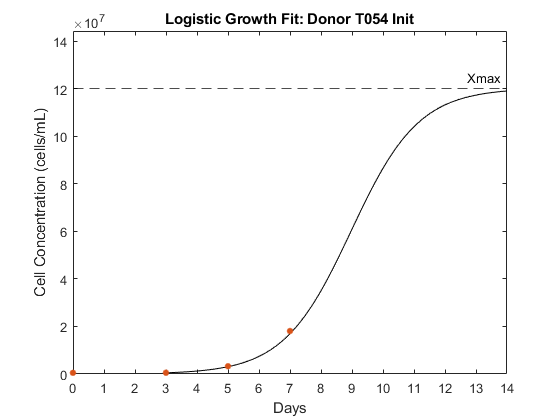

visualize(day,t054,t054init,0:11,'Logistic Growth Fit: Donor T054 Init')

[t054param, t054ssmin] = minError(t054,t054init)

t054param =     7.871e+07      0.96046


t054ssmin =    2.2419e+11


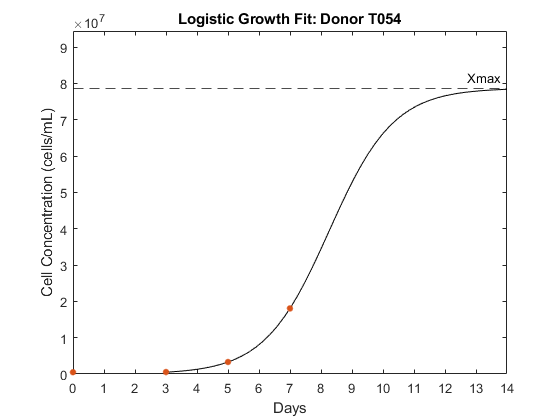

visualize(day,t054,t054param,0:11,'Logistic Growth Fit: Donor T054')

t046init = lmcurvefit(day,t046,[30000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t046init =    5.4224e+07      0.85902


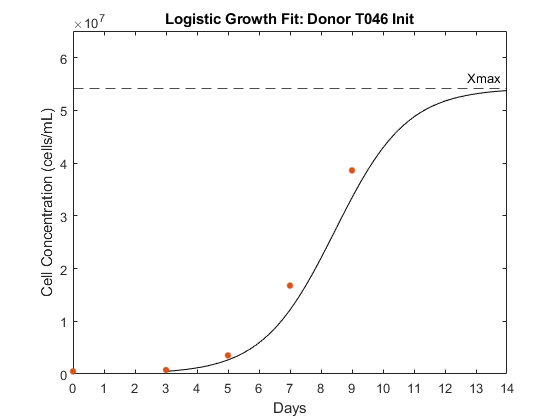

visualize(day,t046,t046init,0:11,'Logistic Growth Fit: Donor T046 Init')

[t046param, t046ssmin] = minError(t046,t046init)

t046param =    4.9003e+07      0.98128


t046ssmin =    3.2817e+11


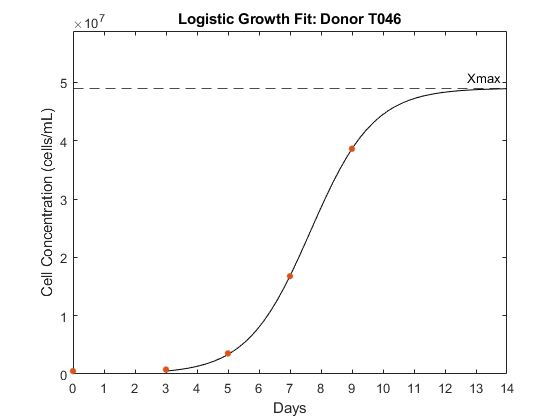

visualize(day,t046,t046param,0:11,'Logistic Growth Fit: Donor T046')

t051init = lmcurvefit(day,t051,[30000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t051init =    2.6373e+07      0.78451


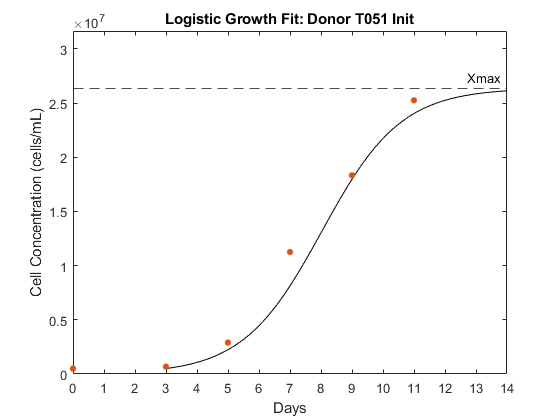

visualize(day,t051,t051init,0:11,'Logistic Growth Fit: Donor T051 Init')

[t051param, t051ssmin] = minError(t051,t051init)

t051param =    2.5625e+07      0.86286


t051ssmin =    5.6362e+12


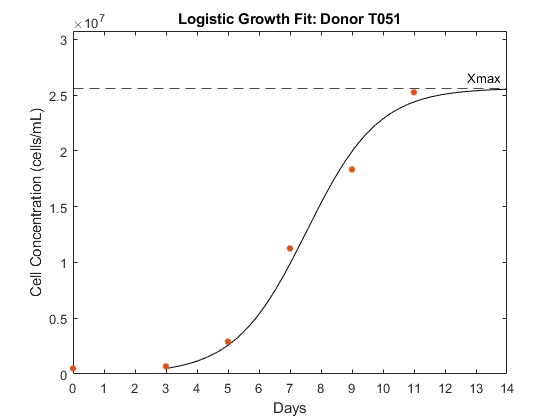

visualize(day,t051,t051param,0:11,'Logistic Growth Fit: Donor T051')

t062init = lmcurvefit(day,t062,[30000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t062init =    2.3106e+07      0.96135


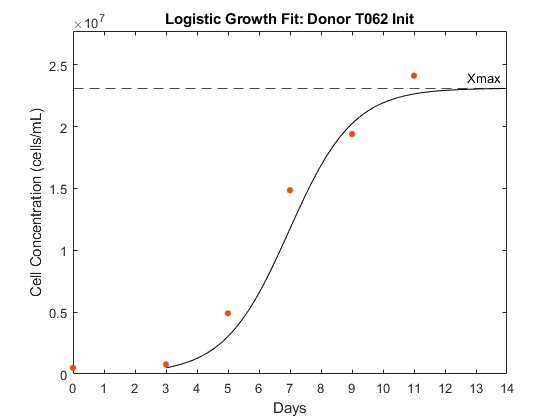

visualize(day,t062,t062init,0:11,'Logistic Growth Fit: Donor T062 Init')

[t062param, t062ssmin] = minError(t062,t062init)

t062param =    2.2667e+07       1.0956


t062ssmin =    7.9411e+12


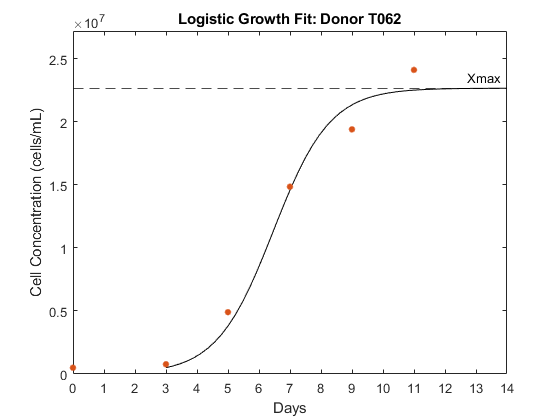

visualize(day,t062,t062param,0:11,'Logistic Growth Fit: Donor T062')

t031mean = mean(t031,2,"omitnan");
t031init = lmcurvefit(day,t031mean,[30000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t031init =    3.9943e+07      0.93943


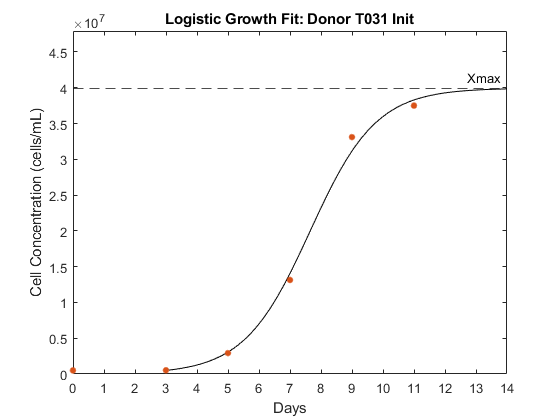

visualize(day,t031mean,t031init,0:11,'Logistic Growth Fit: Donor T031 Init')

[t031param, t031ssmin] = minError(t031,t031init)

t031param =    4.0561e+07      0.94521


t031ssmin =    8.9162e+12


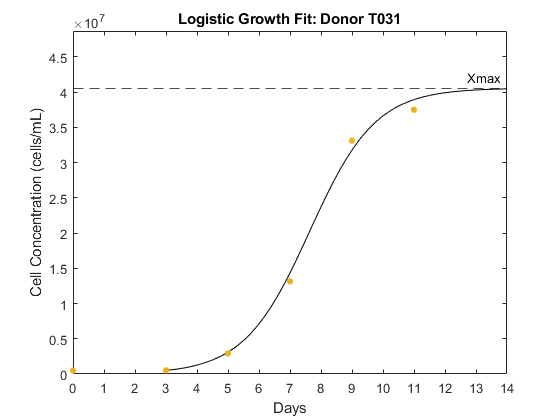

visualize(day,t031,t031param,0:11,'Logistic Growth Fit: Donor T031')

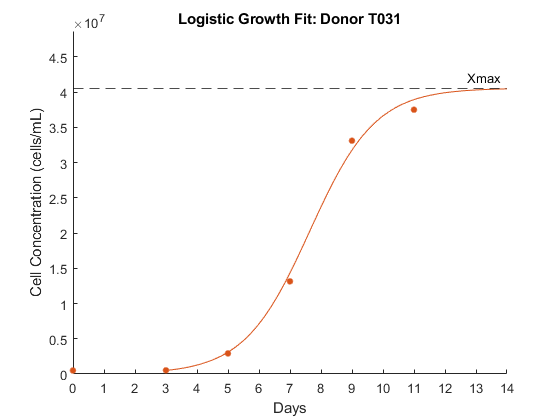

visualize2(day,t031,t031param,0:11,'Logistic Growth Fit: Donor T031')

t052init = lmcurvefit(day,t052,[30000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t052init =     5.184e+07      0.86322


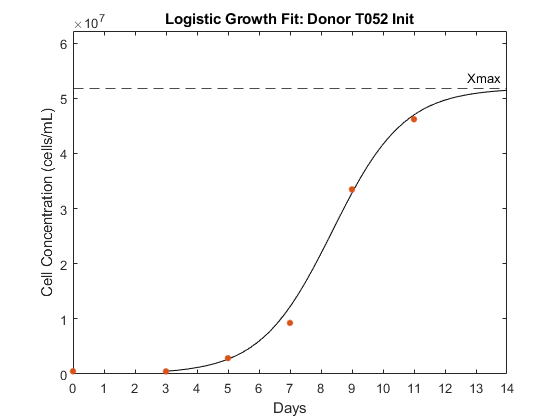

visualize(day,t052,t052init,0:11,'Logistic Growth Fit: Donor T052 Init')

[t052param, t052ssmin] = minError(t052,t052init)

t052param =    5.2106e+07      0.85035


t052ssmin =    8.8238e+12


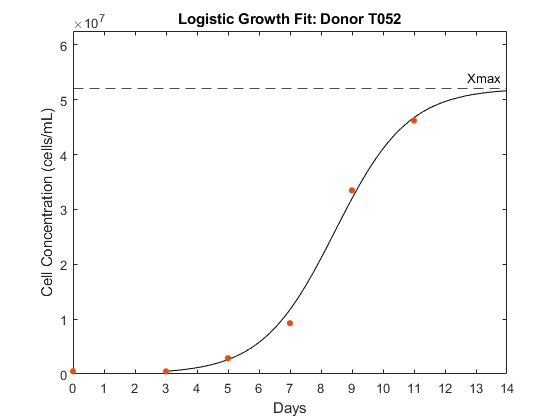

visualize(day,t052,t052param,0:11,'Logistic Growth Fit: Donor T052')

t038init = lmcurvefit(day,t038,[3000000 0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


t038init =    6.4805e+07      0.70442


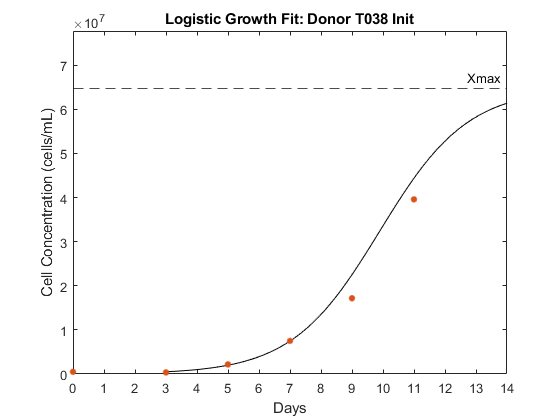

visualize(day,t038,t038init,0:11,'Logistic Growth Fit: Donor T038 Init')

[t038param, t038ssmin] = minError(t038,t038init)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 3087170845792.796387 



t038param =     7.496e+07      0.63905


t038ssmin =    3.0872e+12


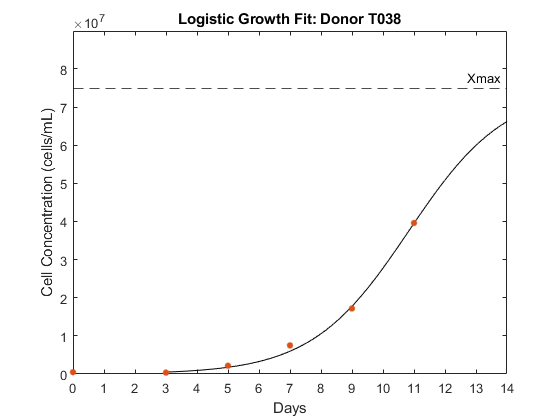

visualize(day,t038,t038param,0:11,'Logistic Growth Fit: Donor T038')

t036mean = mean(t036,2,"omitnan");
[t036param, t036ssmin] = minError(t036,[20000000 0.001])

t036param =    4.4712e+07       1.0164


t036ssmin =    2.3503e+15


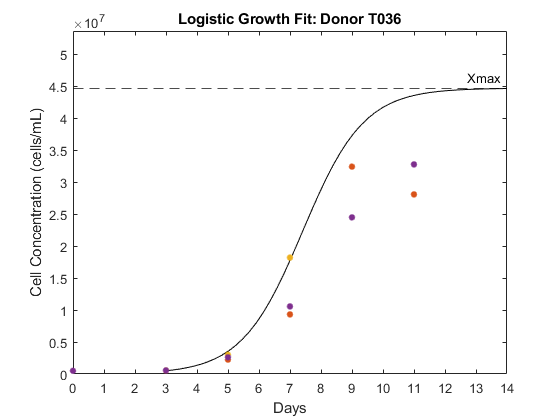

visualize(day,t036,t036param,0:11,'Logistic Growth Fit: Donor T036')

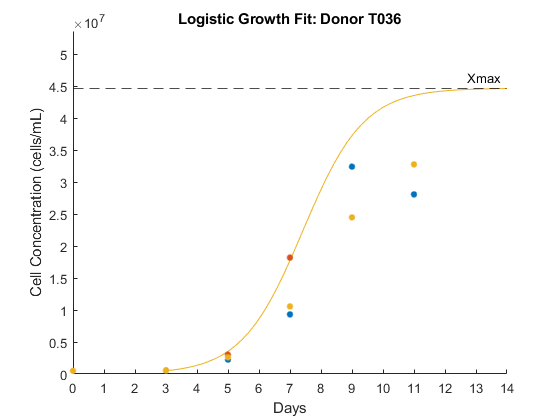

visualize2(day,t036,t036param,0:11,'Logistic Growth Fit: Donor T036')

t066mean = mean(t066,2,"omitnan");
t066init = lmcurvefit(day,t066mean,[30000000 1])


Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


t066init =    5.2115e+07      0.89924


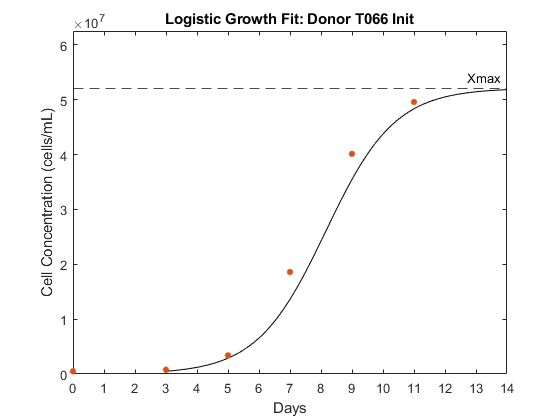

visualize(day,t066mean,t066init,0:11,'Logistic Growth Fit: Donor T066 Init')

[t066param, t066ssmin] = minError(t066,[10000000 1])

t066param =    5.0838e+07       1.0025


t066ssmin =    1.8103e+15


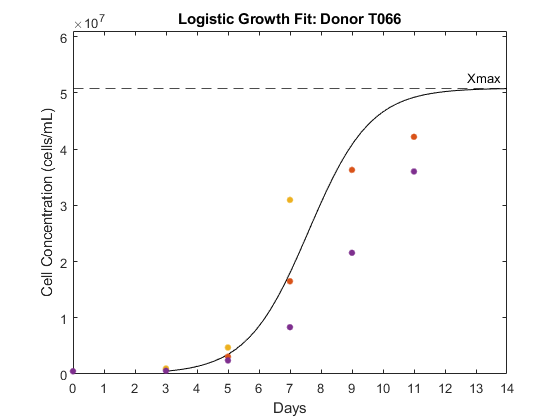

visualize(day,t066,t066param,0:11,'Logistic Growth Fit: Donor T066')

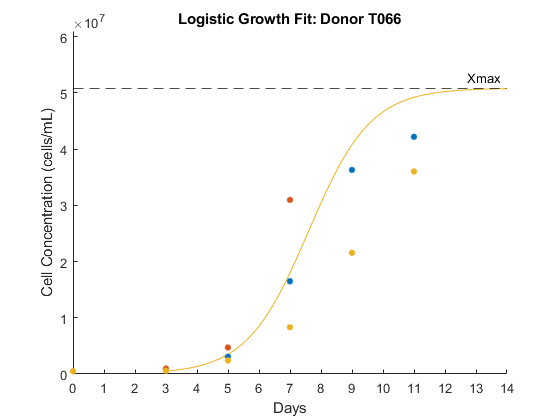

visualize2(day,t066,t066param,0:11,'Logistic Growth Fit: Donor T066')

ua4mean = mean(ua4,2,"omitnan");
ua4init = lmcurvefit(day,ua4mean,[5000000,2])


Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


ua4init =      5000000           2


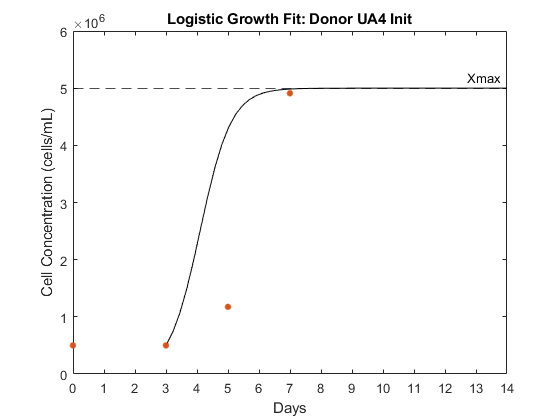

visualize(day,ua4mean,ua4init,0:11,'Logistic Growth Fit: Donor UA4 Init')

[ua4param, ua4ssmin] = minError(ua4,ua4init)

ua4param =    1.0844e+08      0.71344


ua4ssmin =    3.9455e+14


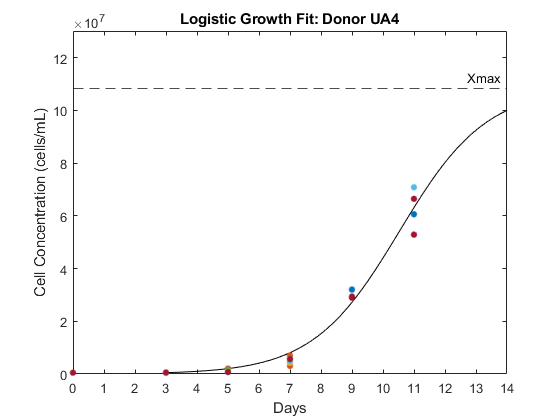

visualize(day,ua4,ua4param,0:11,'Logistic Growth Fit: Donor UA4')

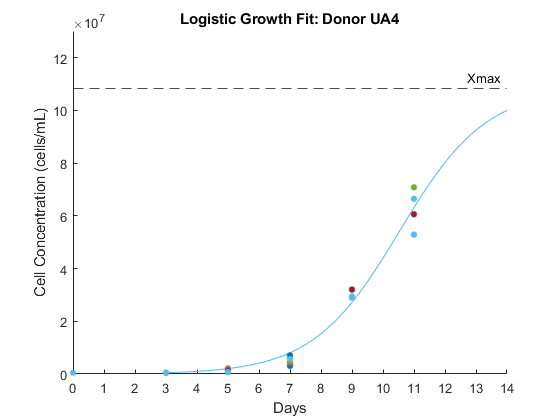

visualize2(day,ua4,ua4param,0:11,'Logistic Growth Fit: Donor UA4')

ua141mean = mean(ua141,2,"omitnan");
ua141init = lmcurvefit(day,ua141mean,[5000000,0.5])


Local minimum possible.
lsqcurvefit stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


ua141init =    1.3192e+08      0.73474


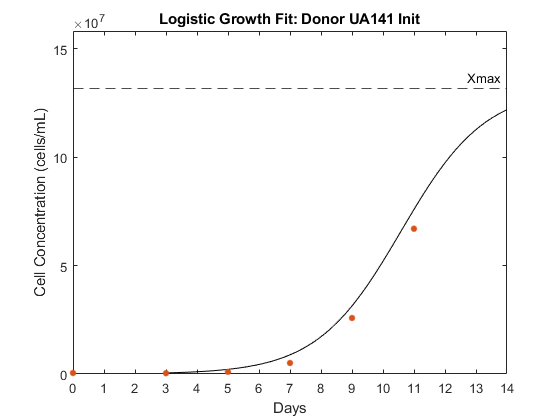

visualize(day,ua141mean,ua141init,0:11,'Logistic Growth Fit: Donor UA141 Init')

[ua141param, ua141ssmin] = minError(ua141,ua141init)

ua141param =    1.6028e+08      0.67999


ua141ssmin =    2.3982e+14


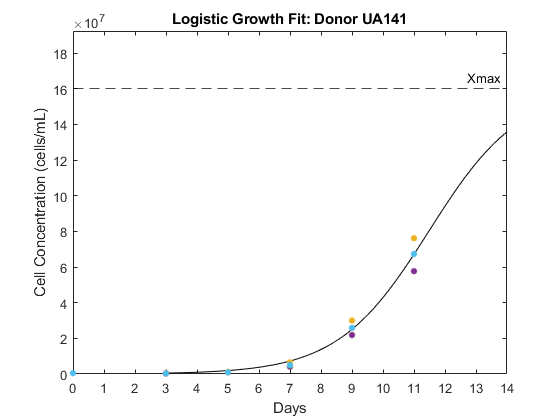

visualize(day,ua141,ua141param,0:11,'Logistic Growth Fit: Donor UA141')

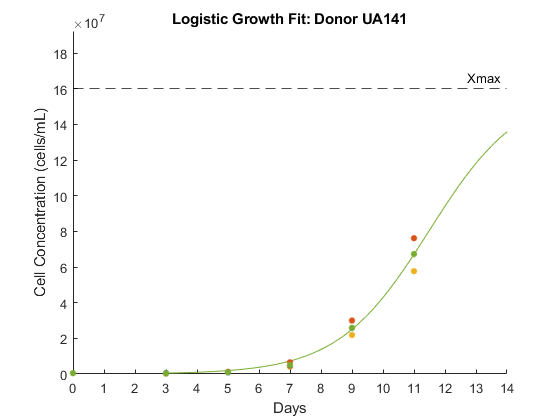

visualize2(day,ua141,ua141param,0:11,'Logistic Growth Fit: Donor UA141')

ua6mean = mean(ua6,2,"omitnan");
ua6init = lmcurvefit(day,ua6mean,[5000000,0.5])


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


ua6init =    2.0372e+07       0.5096


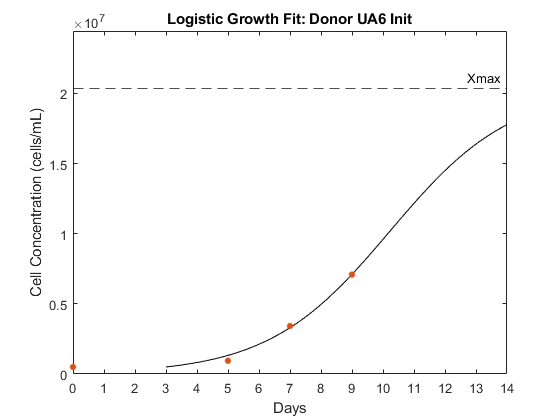

visualize(day,ua6mean,ua6init,0:11,'Logistic Growth Fit: Donor UA6 Init')

[ua6param, ua6ssmin] = minError(ua6,ua6init)

ua6param =    2.1286e+07       0.5061


ua6ssmin =    1.0286e+13


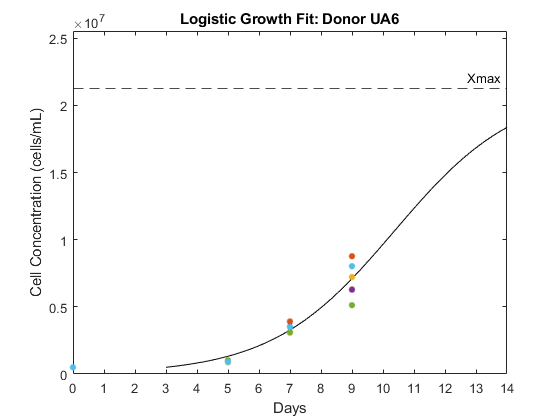

visualize(day,ua6,ua6param,0:11,'Logistic Growth Fit: Donor UA6')

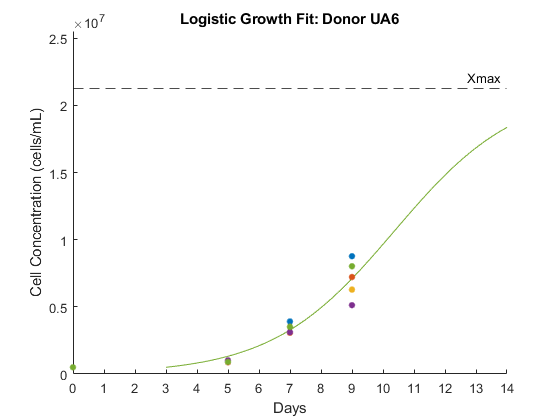

visualize2(day,ua6,ua6param,0:11,'Logistic Growth Fit: Donor UA6')

Generating model fold increase

initcons = 400000:20000:600000;
t054model = modelgen(initcons,t054param,day);
t046model = modelgen(initcons,t046param,day);
t051model = modelgen(initcons,t051param,day);
t062model = modelgen(initcons,t062param,day);
t031model = modelgen(initcons,t031param,day);
t052model = modelgen(initcons,t052param,day);
t038model = modelgen(initcons,t038param,day);
t036model = modelgen(initcons,t036param,day);
t066model = modelgen(initcons,t066param,day);
ua4model = modelgen(initcons,ua4param,day);
ua141model = modelgen(initcons,ua141param,day);
ua6model = modelgen(initcons,ua6param,day);
models = [t054model t046model t051model t062model t031model t052model t038model ...
    t036model t066model ua4model ua141model ua6model]

models =         4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05
        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05      4.8e+05        5e+05      5.2e+05      5.4e+05      5.6e+05      5.8e+05        6e+05        4e+05      4.2e+05      4.4e+05      4.6e+05  

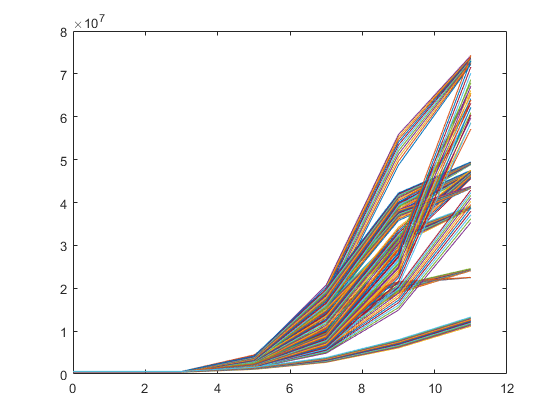

plot(day,models)

modelfoldincs = modelfoldincgen(models)

modelfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1        

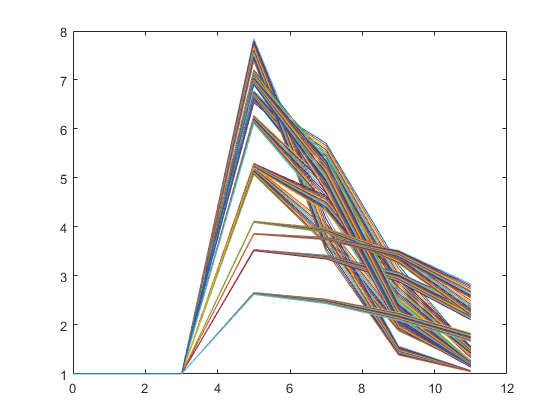

plot(day,modelfoldincs)


writematrix(modelfoldincs,"modelfoldincs.txt")
writematrix(initcons,"modelinitcons.txt")

Generating cell con fold increase

rawfoldincs = readmatrix("cell con fold increase.xlsx");
rawfoldincs(:,1)=[]

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377       1.1583       1.0556        0.962        1.076         0.94         0.94         1.13          0.9         0.83        0.865         1.05         0.94         1.17         1.13         0.94         0.38          0.6       0.7625            1            1            1            1            1
       6.1224       4.

rawinitcons = readmatrix("true con.xlsx");
rawinitcons(:,1)=[];
rawinitcons(2:end,:) = []

rawinitcons =       500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      360000      360000      500000      500000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      500000      500000      500000      500000      500000



writematrix(rawfoldincs,"rawfoldincs.txt")
writematrix(rawinitcons,"rawinitcons.txt")

Save model parameters

allparams = [t054param;
    t046param;
    t051param;
    t062param;
    t031param;
    t052param;
    t038param;
    t036param;
    t066param;
    ua4param;
    ua141param;
    ua6param]

allparams =     7.871e+07      0.96046
   4.9003e+07      0.98128
   2.5625e+07      0.86286
   2.2667e+07       1.0956
   4.0561e+07      0.94521
   5.2106e+07      0.85035
    7.496e+07      0.63905
   4.4712e+07       1.0164
   5.0838e+07       1.0025
   1.0844e+08      0.71344


writematrix(allparams,"alllogparams.txt")

meancons = [t054 t046 t051 t062 t031mean t052 t038 t036mean t066mean ua4mean ua141mean ua6mean]

meancons =         5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05        5e+05
     5.39e+05     7.65e+05     6.79e+05     7.74e+05     5.26e+05      4.7e+05     3.59e+05   5.6774e+05   7.7465e+05   5.0065e+05   3.8125e+05          NaN
      3.3e+06   3.5311e+06   2.9009e+06   4.9076e+06   2.9219e+06     2.88e+06     2.18e+06   2.6249e+06   3.4038e+06   1.1746e+06   9.9844e+05    9.446e+05
    1.807e+07   1.6782e+07   1.1261e+07   1.4855e+07   1.3149e+07   9.2697e+06   7.5077e+06   1.2707e+07   1.8602e+07   4.9112e+06   5.0879e+06   3.4239e+06
          NaN   3.8619e+07   1.8337e+07   1.9403e+07   3.3109e+07   3.3481e+07   1.7182e+07   4.4338e+07   4.0137e+07   3.0606e+07   2.5872e+07   7.0874e+06
          NaN          NaN   2.5254e+07   2.4117e+07   3.7505e+07    4.621e+07   3.9604e+07   3.9266e+07   4.9591e+07   6.2695e+07   6.7039e+07          NaN


writematrix(meancons,"meancons500k.txt")

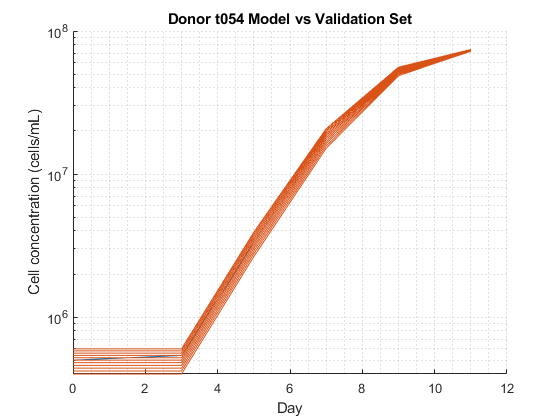

figure
hold on
plot(day,t054,"Color",[0, 0.4470, 0.7410])
plot(day, t054model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t054 Model vs Validation Set")
hold off

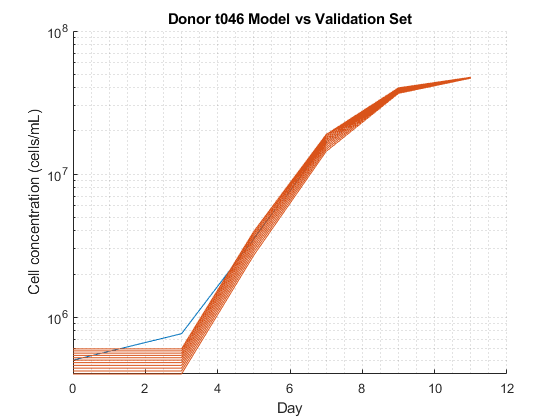

figure
hold on
plot(day,t046,"Color",[0, 0.4470, 0.7410])
plot(day, t046model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t046 Model vs Validation Set")
hold off

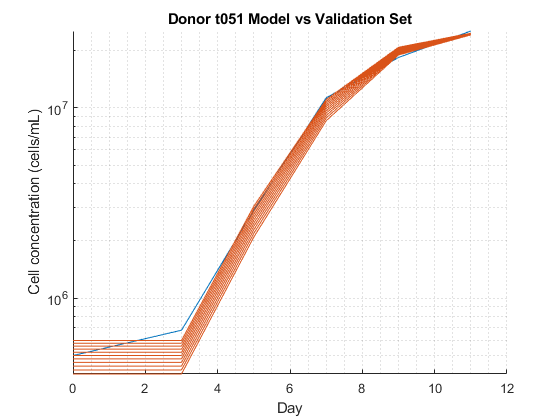

figure
hold on
plot(day,t051,"Color",[0, 0.4470, 0.7410])
plot(day, t051model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t051 Model vs Validation Set")
hold off

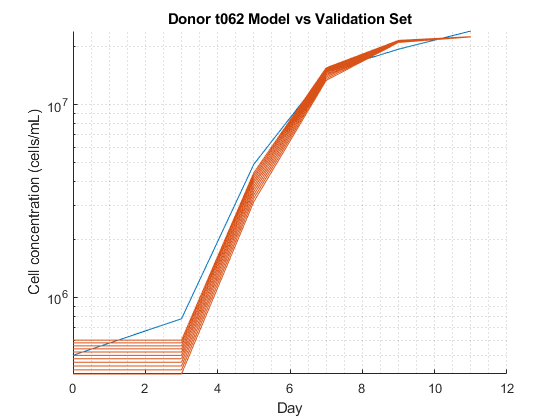

figure
hold on
plot(day,t062,"Color",[0, 0.4470, 0.7410])
plot(day, t062model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t062 Model vs Validation Set")
hold off

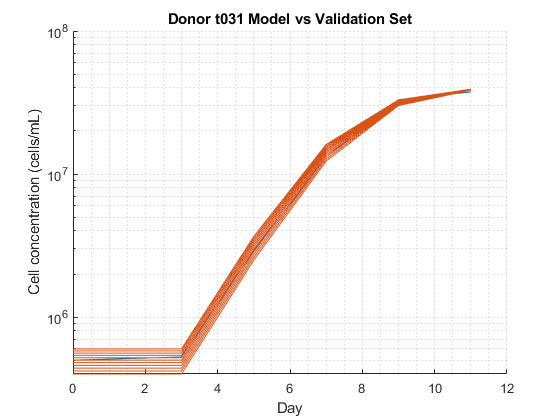

figure
hold on
plot(day,t031,"Color",[0, 0.4470, 0.7410])
plot(day, t031model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t031 Model vs Validation Set")
hold off

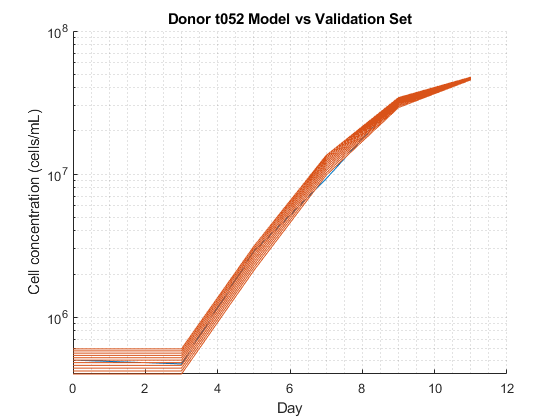

figure
hold on
plot(day,t052,"Color",[0, 0.4470, 0.7410])
plot(day, t052model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t052 Model vs Validation Set")
hold off

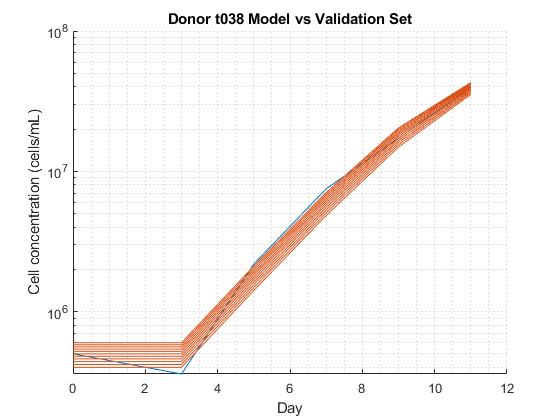

figure
hold on
plot(day,t038,"Color",[0, 0.4470, 0.7410])
plot(day, t038model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t038 Model vs Validation Set")
hold off

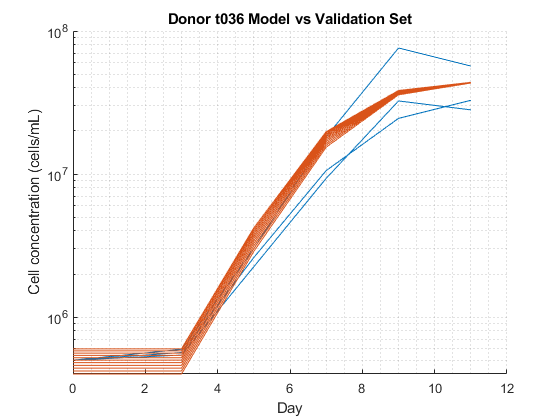

figure
hold on
plot(day,t036,"Color",[0, 0.4470, 0.7410])
plot(day, t036model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t036 Model vs Validation Set")
hold off

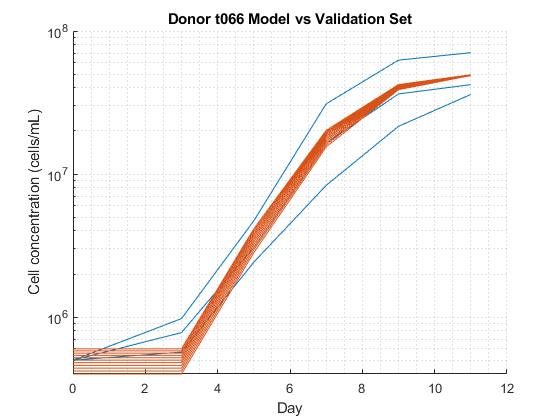

figure
hold on
plot(day,t066,"Color",[0, 0.4470, 0.7410])
plot(day, t066model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor t066 Model vs Validation Set")
hold off

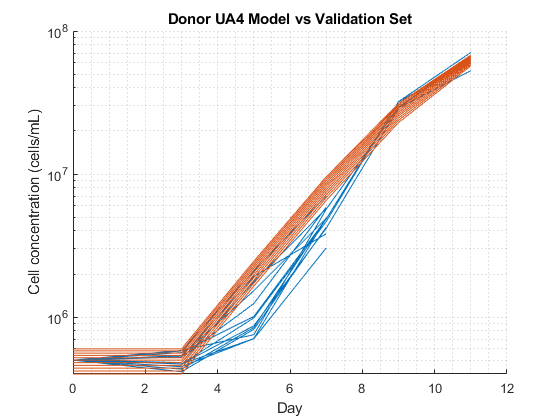

figure
hold on
plot(day,ua4,"Color",[0, 0.4470, 0.7410])
plot(day, ua4model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor UA4 Model vs Validation Set")
hold off

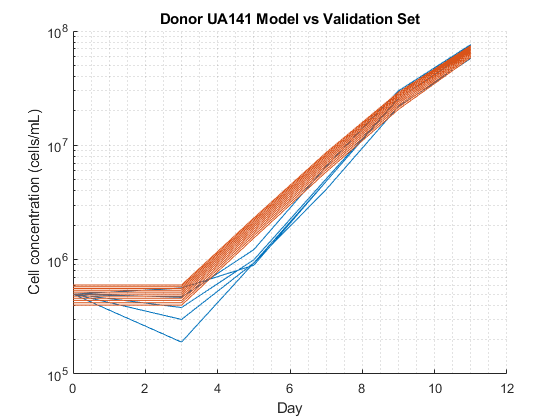

figure
hold on
plot(day,ua141,"Color",[0, 0.4470, 0.7410])
plot(day, ua141model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor UA141 Model vs Validation Set")
hold off

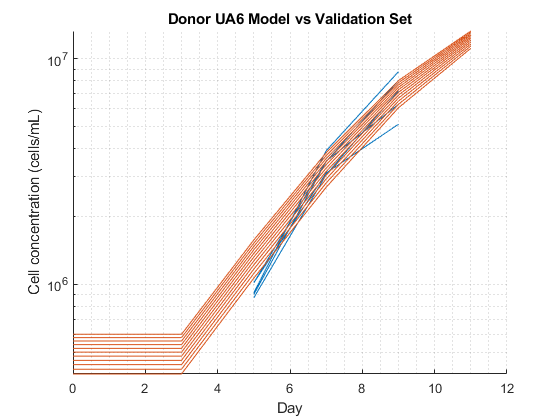

figure
hold on
plot(day,ua6,"Color",[0, 0.4470, 0.7410])
plot(day, ua6model,"Color",[0.8500, 0.3250, 0.0980])
grid minor 
set(gca, 'YScale', 'log')
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
title("Donor UA6 Model vs Validation Set")
hold off

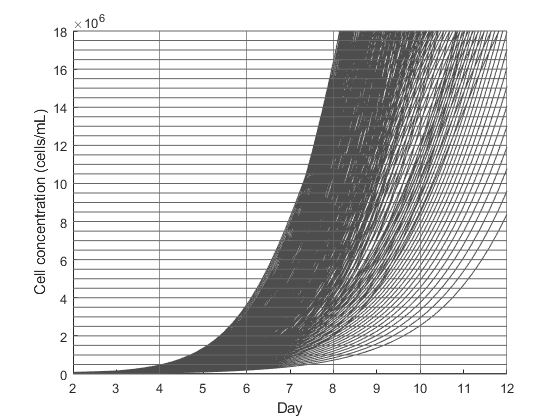

initcon = 30000:5000:160000;
t = 3:2:11;

figure
hold on

moderes = linspace(2,12,50);
transparency = 1;
modelcolour = {[1 1 1]*0.3,[1 1 1]*0.5};

for j=1:size(allparams,1)-3
    for i=1:numel(initcon)
        pmodel = LGE(allparams(j,:),moderes,initcon(i));
        p = plot(moderes,pmodel,'-','Color',modelcolour{1},"LineWidth",0.5);
        p.Color(4) = transparency;
    end
end

bounds1 = 0:500000:18000000;
bounds2 = 0:500000:18000000;

gridcolour = [1 1 1]*0.4;

for i=1:numel(bounds1)
    plot(2:6,[bounds1(i) bounds1(i) bounds1(i) bounds1(i) bounds1(i)],"-","Color",gridcolour)
end
for i=1:numel(bounds2)
    plot(6:12,[bounds2(i) bounds2(i) bounds2(i) bounds2(i) bounds2(i) bounds2(i) bounds2(i)],"-","Color",gridcolour)
end

xline(4,"-","Color",gridcolour)
xline(6,"-","Color",gridcolour)
xline(8,"-","Color",gridcolour)
xline(10,"-","Color",gridcolour)
xline(12,"-","Color",gridcolour)
xlabel("Day")
ylabel("Cell concentration (cells/mL)")
ylim([0,1.8e7])
xlim([2,12])
% title("Stochastic Model and Value Function Approximator","FontWeight","bold")
hold off

function a = lmcurvefit(day,expcon,a0)  
    if any(ismissing(expcon(2)))
        expcon(2) = expcon(1);
    end
    
    day(1) = [];
    expcon(1) = [];
   
    options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt', ... 
    'MaxFunctionEvaluations',5000000,'MaxIterations',100000,"FunctionTolerance",1e-8);
   
    avdata = ~ismissing(expcon);
    P = expcon(avdata);
    t = day(avdata);
    
    if size(P,1) < 2
        disp(['This iteration is skipped because there ' ...
        'are less than 2 valid data points for curve-fitting'])
        a = [NaN NaN]
    else 
        x0 = P(1);
        func = @(a,t) LGE(a,t,x0);
        a = lsqcurvefit(func,a0,t,P,[],[],options);
    end
end

function visualize(day,con,a,xwindow,tle)
    x0 = con(1,1);
    moderes = linspace(xwindow(1)+3,xwindow(end)+3,50);
    ymax = a(1)*1.2;
    fig = figure;
    plot(moderes,LGE(a,moderes,x0),'k-');
    hold on
    plot(day,con,'.','MarkerSize',15);
    yline(a(1),'k--','Xmax');
    hold off

    title(tle)
    xlabel('Days')
    ylabel('Cell Concentration (cells/mL)')
    ylim([0,ymax])
    xlim([xwindow(1),xwindow(end)+3])
    xticks(0:1:xwindow(end)+3)
%     set(gca, 'YScale', 'log')
end

function visualize2(day,con,a,xwindow,tle)
    moderes = linspace(xwindow(1)+3,xwindow(end)+3,50);    
    ymax = a(1)*1.2;
    fig = figure;
    hold on
    for i=1:size(con,2)
        plot(moderes,LGE(a,moderes,con(1,i)),'-');
    end
    set(gca,'ColorOrderIndex',1)
    plot(day,con,'.','MarkerSize',15);
    yline(a(1),'k--','Xmax');
    hold off

    title(tle)
    xlabel('Days')
    ylabel('Cell Concentration (cells/mL)')
    ylim([0,ymax])
    xlim([xwindow(1),xwindow(end)+3])
    xticks(0:1:xwindow(end)+3)
%     set(gca, 'YScale', 'log')
end

function [parameters, ssmin] = minError(data, initVal)
    fun = @(x)evalFuN(x,data);
    [parameters,ssmin]=fminsearch(fun,initVal,[]);
end

function errorFun = evalFuN(PARAMS,data)
    
    nbatch = size(data,2);
    
    A  = PARAMS(1);
    D  = PARAMS(2);
    
    errorFun =0;
    
    for k = 1:nbatch
        
        availTime = ~ismissing(data(:,k));
        % for each time step(change here!!!!)
        timeData = [0 3 5 7 9 11];
        timeData = timeData(availTime);
        conData = data(availTime,k);
        x0 = conData(1);
        
        for i=1:numel(conData)
            
            %(change here!!!!)
            t= timeData(i);
            yTarget = conData(i);
            
            % logistic function
            % I changed it to the logistic growth equation
            yPredicted = A./(1+((A-x0)./x0).*exp(-1*D.*(t-3)));
            
            errorFun = errorFun + (sum(yPredicted-yTarget).^2);
    
        end
    end
end

function model = modelgen(initcons,logparams,t) 
    model = zeros(6,numel(initcons));
    for i=1:numel(initcons)
        model(:,i) = LGE(logparams,t,initcons(i));
        model(1,i) = initcons(i);
    end
end

function modelfoldinc = modelfoldincgen(models)
    modelfoldinc = ones(6,size(models,2));
    for i=1:size(modelfoldinc,2)
        for j=3:6
            modelfoldinc(j,i)=models(j,i)/models(j-1,i);
        end
    end
end